# Tabletop problem for study 

This livescript builds a tabletop planning problem that consists of 

- a width x height world grid.

- an agent, can be a robot, satellite, uav, etc. The agent can move (up, down, left, right) or perform other actions, which deplete the battery

- a discretized battery model (4 states, [1,2,3,4], 1 is fully charged to steady state, 2 is steady state, 3 is steady to decline, 4 is decline - end of charge. [wip] --> moving one "normal" square depletes 3% soc, moving one "bad" square depletes 5% soc, taking a picture depletes 1%, transmitting the picture depletes 2% (some of this isn't implemented yet)

## General Setup

- The map

width = 8;
height = 8;

% start location
start = [1,1];
finish = start;

% location prototype
location.type = "normal"; 
location.label = "";

% map is a matrix of structs
map = repmat(location, 8, 8);

- The agent

agent.type = "robot";
agent.location = start;
agent.distance = 0;
agent.direction = '^';
agent.soc = 100;
agent.locationType = location.type;
agent.cumulativeReward = int16(0);

- actions (move up, down, left, right, observe, transmit

actions = ['^', 'v', '<', '>', 'o', 't'];


## Keep track of State

state.location = agent.location;
state.battery = 1;
state.achieved1 = false;
state.achieved2 = false;
state.reward = 0;

## The world grid

- add "points of interest"

- References are hard-coded throughout, however their location values, lengths, and names can be changed

- Update the locations here

poi.start = agent.location;
poi.objectives = [8,5; 2,6];
poi.pitfalls = [2,5; 4,1; 6,2; 8,2; 6,6; 6,7; 7,7];
poi.blocks = [1,4; 4,3; 6,3; 5,3; 2,2; 5,4; 5,5];

- update location names here

map(poi.start(1), poi.start(2)).type = "start";
for i=1:(length(poi.objectives))
    map(poi.objectives(i,1), poi.objectives(i,2)).type = "objective";
    map(poi.objectives(i,1), poi.objectives(i,2)).label = sprintf("O-%d", i);
end

for i=1:(length(poi.pitfalls))
    map(poi.pitfalls(i,1), poi.pitfalls(i,2)).type = "pitfall";
    map(poi.pitfalls(i,1), poi.pitfalls(i,2)).label = sprintf("P-%d", i);
end
for i=1:(length(poi.blocks))
    map(poi.blocks(i,1), poi.blocks(i,2)).type = "block";
end

### Visualize the grid world

- show location of robot and objects 

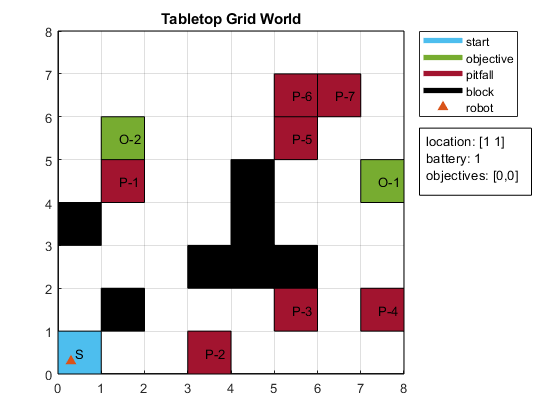

f1 = visualizeGridWorld(1, map, poi, state, agent);
title("Tabletop Grid World");

### [optional] Move the robot, and revisualize

- The robot cannot travel off of the grid or on a black spot

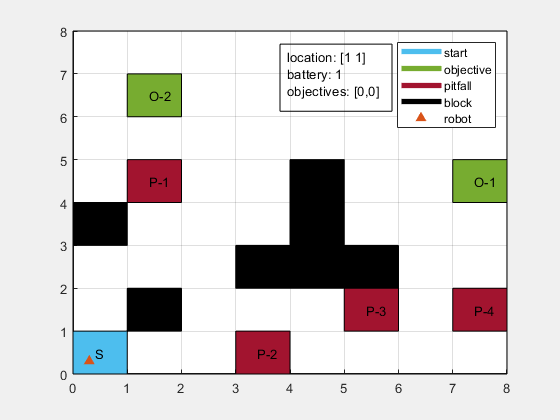

agent = moveAgent(agent, '>', 1, map, poi);
state = update_state(state, agent, map);
f2 = visualizeGridWorld(2, map, poi, state, agent);

### [optional] Robot Teleop

- reads arrow keys, q to quit (press enter to close pop up figure)

- run above block to generate figure 2

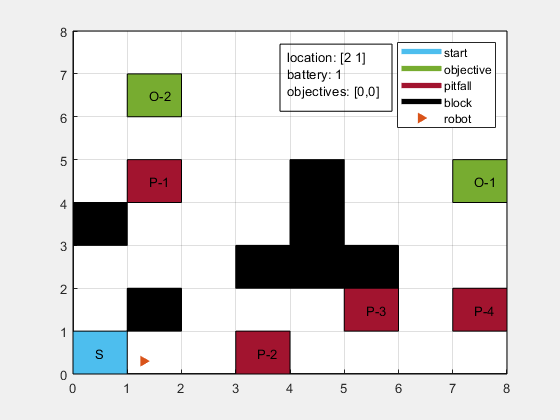

teleop(agent, 2, map, poi, state);

## Shortest path test

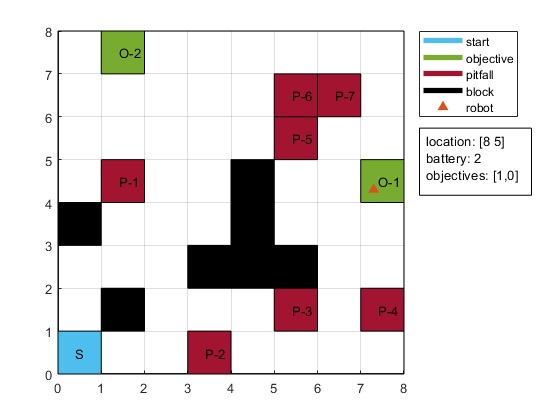

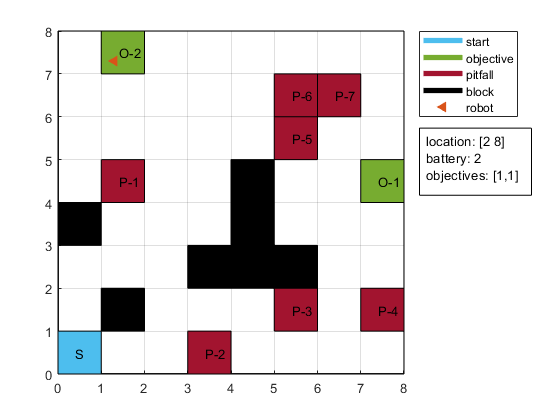

G = convert2graph(map, "block", "pitfall");
start_ID = 1;
obj1_ID = 40;
obj2_ID = 58;

[P, d, edgepath] = shortestpath(G, start_ID, obj1_ID);
dirs = get_path_directions(map, P);

%reset agent and state 
state.location = agent.location;
state.battery = 1;
state.achieved1 = false;
state.achieved2 = false;

agent = set_agent(agent, map, [1,1], 0, '^', 100, 1, 0);
for i=1:length(dirs)
    f3 = visualizeGridWorld(3, map, poi, state, agent);
    if i < length(dirs)
        agent = moveAgent(agent, dirs(i), 1, map, poi);
        state = update_state(state, agent, map);
    end
    pause(.3);
end

## How to generate the state space now?